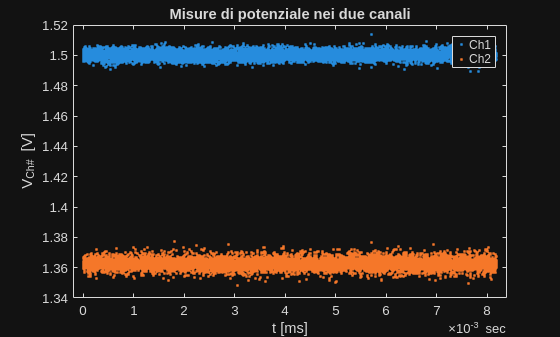

(fileparts(matlab.desktop.editor.getActiveFilename));
tbl = readtable("misura07.txt",NumHeaderLines=3);
% Rinominiamo subito le variabili
tbl.Properties.VariableNames = ["timestamp" "Ch1" "Ch2"];
% l'accesso alle singole colonne di dati è banale
tbl.Ch1;
t0 = tbl.timestamp(1);                 % Recuperiamo il tempo di inizio della misiura
tbl.t = seconds(tbl.timestamp-t0);     % Convertiamo il tempo passato in unità gestibili
tbl.timestamp = [];                    % Eliminiamo la colonna timestamp
plot(tbl.t, [tbl.Ch1 tbl.Ch2],'.');
title("Misure di potenziale nei due canali");
legend("Ch1","Ch2");
xlabel("t [ms]");
ylabel("V_{Ch#} [V]");

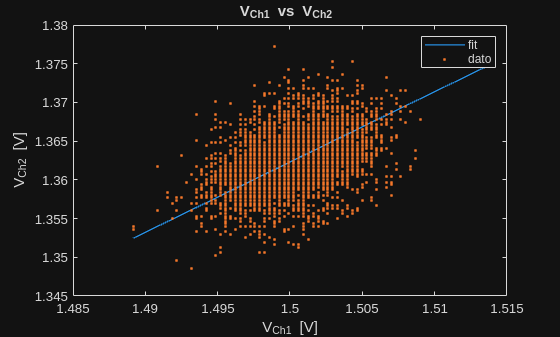



% Parametri di partenza (sceglieteli bene! e` fondamentale)
pp0 = [0.9];

fitfunc = @(p, x) x/(1+p(1));
% Nella sua versione piu` basic, il fit si fa come segue
pp = nlinfit(tbl.Ch1,tbl.Ch2,fitfunc,pp0)';

% Plottiamolo in cima al dato
% questo dice a MATLAB di continuare a disegnare sullo stesso plot
plot(tbl.Ch1,fitfunc(pp,tbl.Ch1), LineWidth=1);
hold on;
plot(tbl.Ch1,tbl.Ch2, '.', LineWidth=1);
hold off;   % e questo gli dice di smettere e tornare alla modalita` standard
            % i.e. ogni plot finisce su un grafico nuovo

legend("fit","dato",Location="NE");
title("V_{Ch1} vs V_{Ch2} ");
xlabel("V_{Ch1} [V]");
ylabel("V_{Ch2} [V]");

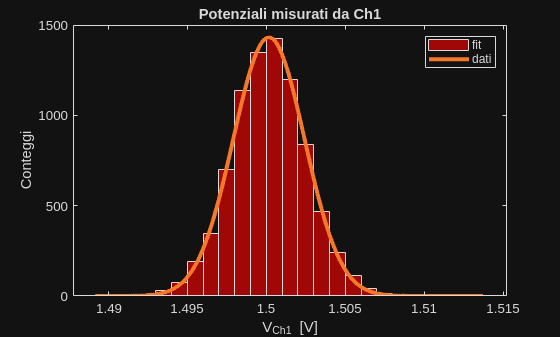

gauss=@(p,x)p(1).*exp(-((x-p(2))/(2*p(3))).^2);

pp1=[1500,1.5,0.001];

h1=histogram(tbl.Ch1, 'FaceColor', 'r','BinWidth', 0.001);  % istogramma rosso
binCenters1 = h1.BinEdges(1:end-1) + diff(h1.BinEdges)/2;


hold on

pph1 = nlinfit(binCenters1,h1.BinCounts,gauss,pp1)';
xx1=linspace(min(tbl.Ch1),max(tbl.Ch1),1000);
plot(xx1,gauss(pph1,xx1), LineWidth=3);

hold off

title("Potenziali misurati da Ch1");
xlabel("V_{Ch1} [V]");
ylabel("Conteggi");
legend("fit","dati",Location="NE");

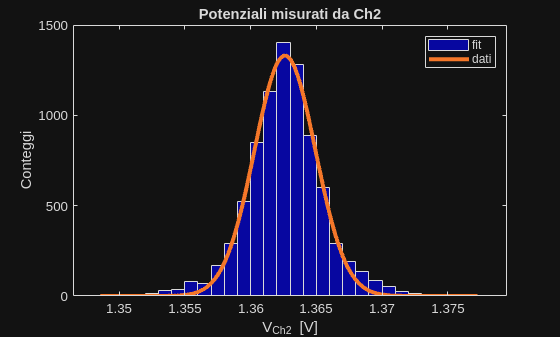

pp2=[1500,1.36,0.001];
h2=histogram(tbl.Ch2, 'FaceColor', 'b','BinWidth', 0.001);  % istogramma blu
binCenters2 = h2.BinEdges(1:end-1) + diff(h2.BinEdges)/2;

hold on

xx2=linspace(min(tbl.Ch2),max(tbl.Ch2),1000);
pph2 = nlinfit(binCenters2,h2.BinCounts,gauss,pp2)';
plot(xx2,gauss(pph2,xx2), LineWidth=3);

hold off

title("Potenziali misurati da Ch2")
xlabel("V_{Ch2} [V]");
ylabel("Conteggi");
legend("fit","dati",Location="NE");